# Project 1

### What Galileo learned about pendulums

The goal for this project is to measure the angular displacement from staright vertical ($\theta$ = 0 rads). This will be given by the function $u(t)$, modeled by the *nonlinear pendulum equation*:


$$\ddot u = -\frac{g}{L}\sin(u)$$


For this model we will assume the following conditions:


$$g = 32 \frac{ft}{s^2}$$



$$L = 1$$


#### Section 1 - Create chebop and solve

Initial conditions: $u(0) = 0.1$ and $\dot u(0) = 0$, over the interval $[0, 6]$.

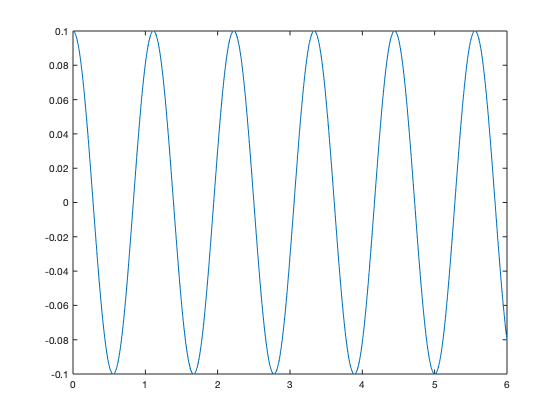

clc
clear
%clearing command window and workspace IOT avoid errors
g = 32;
L = 1;
N = chebop(@(u) diff(u,2) + ((g/L)*sin(u)), [0, 6]);
N.lbc = [0.1, 0];
u = N\0;
plot(u)

#### Section 2 - Determine the period

[mval, mpos] = max(u, 'local');
mpos = mpos';
period = diff(mpos);

#### Section 3 - Altering ICs

c = [0.5,1];
new_period = zeros(2,length(mpos)-1);
for i = 1:2
    N.lbc = [c(i), 0];
    u = N\0;
    [~, mpos] = max(u, 'local');
    mpos = mpos';
    new_period(i,:) = diff(mpos);
end


The results show in Table 1 below that as $u(0)$ increases, the $period$of the function also increases.


$$\matrix{\quad{\textbf{u(0)}\quad{\textbf{Period}}\cr\quad{0.1} \quad{1.1114} \cr\quad{0.5} \quad{1.1283} \cr\quad{1.0} \quad{1.1844}}$$



$$Table\ 1:\ Changes\ in\ period\ as\ u(0)\ increases$$


#### Section 4 - Altering pendulum length

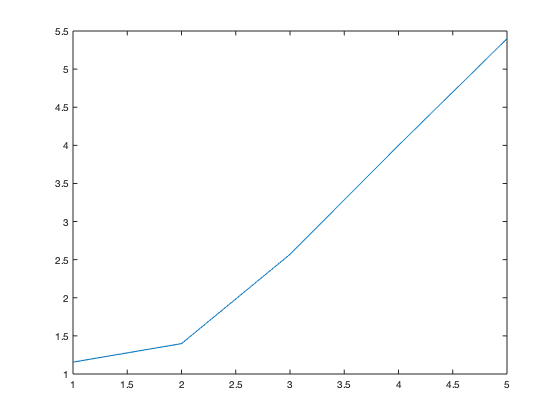

l = [2, 4, 8, 16, 32];
newl_period = zeros(1,2);
for i = 1:length(l)
    N = chebop(@(u) diff(u,2) + ((g/l(i))*sin(u)), [0, 6]);
    N.lbc = [0.1, 0];
    u = N\0;
    [~, mpos] = max(u, 'local');
    mpos = mpos'; 
    difference = diff(mpos);
    newl_period(i) = difference(end);
    Doubling_effect(i) = newl_period(i)/period(1);
end
l2 = log2(l);
plot(l2, Doubling_effect)

This looks as though it could be an exponential curve. Let's fit an exponential curve to the data set to find an estimated function for $T_p$

f = fit(l2',Doubling_effect','exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.7636  (0.4123, 1.115)
       b =       0.396  (0.2912, 0.5009)

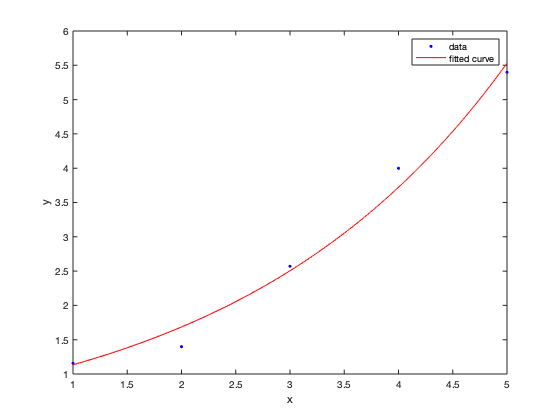

plot(f,l2',Doubling_effect')

The relationship of the period of the pendulum $T_p$ to the length $L$ has been estimated to be the following:


$$f(x) \approx 0.76e^{0.4x}$$


where


$$x = log_2L
$$


#### Section 5 - Solving for a specified period

Now we just code in our previously found function for the period and verify

f = @(x) 0.76*exp(0.4*x);
for i=1:0.01:10
    T = f(i);
    if T >= 2
        break
    end
end
L_solved = 2^i;
statement = sprintf('To have a period of 2 seconds, L = %.2f m', L_solved);
disp(statement)

To have a period of 2 seconds, L = 5.35 m


As previously stated, the function above is an estimate for $T_p$ as a function of $L$. At $L = 5.35\ m$, $T_p = 2.0008\ s$.